for i=1:1:time;
    Ucam(:,i)=squeeze(mean(uprom(:,:,i),1));
    Wcam(:,i)=squeeze(rms(uprim(:,:,i),1));
    Tcam(:,i)=squeeze(mean(tprom(:,:,i),1));
    Tcam2(:,i)=squeeze(rms(tprim(:,:,i),1));
    % Tcam(:,i)=squeeze(mean(tprom(:,:,i),1));
end 
ejez3=(repmat(ejez,time,1))';
proHprom=5940.*squeeze(mean((wprim.*tprim),1));
dh=diff(proHprom,1,1)./diff(ejez3,1,1);
du=diff(Ucam,1,1)./diff(ejez3,1,1);
dt=diff(Tcam,1,1)./diff(ejez3,1,1);
dt2=diff(Tcam2,1,1)./diff(ejez3,1,1);
dw=diff(Wcam,1,1)./diff(ejez3,1,1);
dtke=diff(TKE(:,1:time),1,1)./diff(ejez3,1,1);
ejez3=interp1(ejez,1:1:length(ejez)-1);

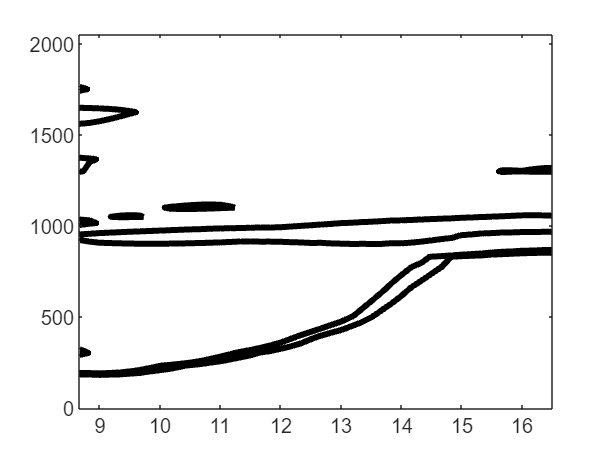

v = [0.0001 0.0005 0.00007];
[C,h]=contour(timebar(1:1:time).*10/60+8.5,ejez3,dt,v,'EdgeColor','black');
% clabel(C,h, 'FontSize', 10, 'Color','white');
h.LineWidth = 3;
ylim([0 2050])

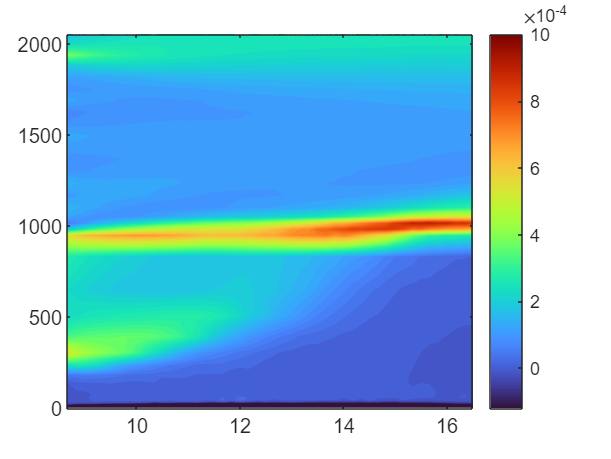

v = [0.03 0.0001 -0.1];
[C,h]=contourf(timebar(1:1:time).*10/60+8.5,ejez3,dt,500,'EdgeColor','none');
% clabel(C,h, 'FontSize', 10, 'Color','white');
h.LineWidth = 3;
ylim([0 2050])
clim([-0.00012, 0.001])
colormap(turbo), colorbar
c = colorbar;

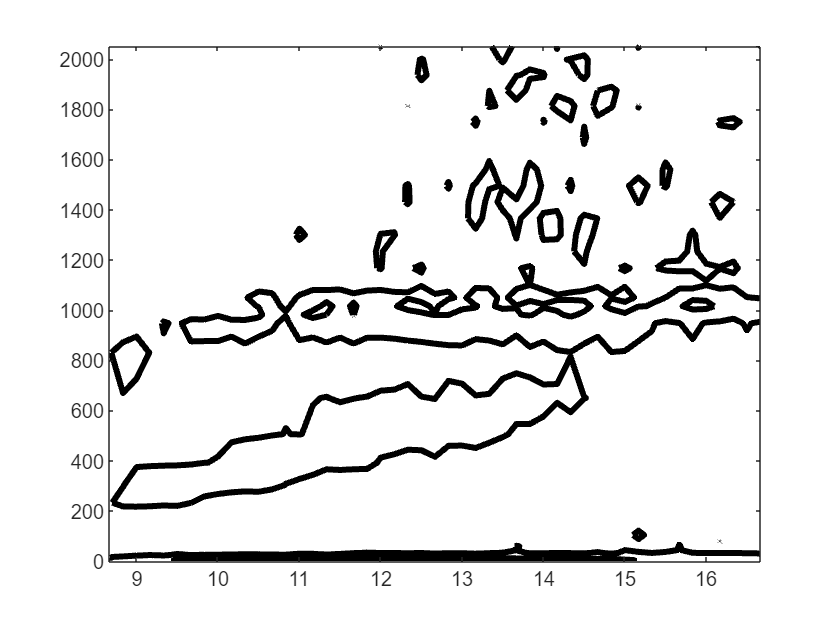

v = [0.03 0.0001 -0.1];
[C,h]=contour(timebar(1:1:time).*10/60+8.5,ejez3,dh,v,'EdgeColor','black');
% clabel(C,h, 'FontSize', 10, 'Color','white');
h.LineWidth = 3;
ylim([0 2050])

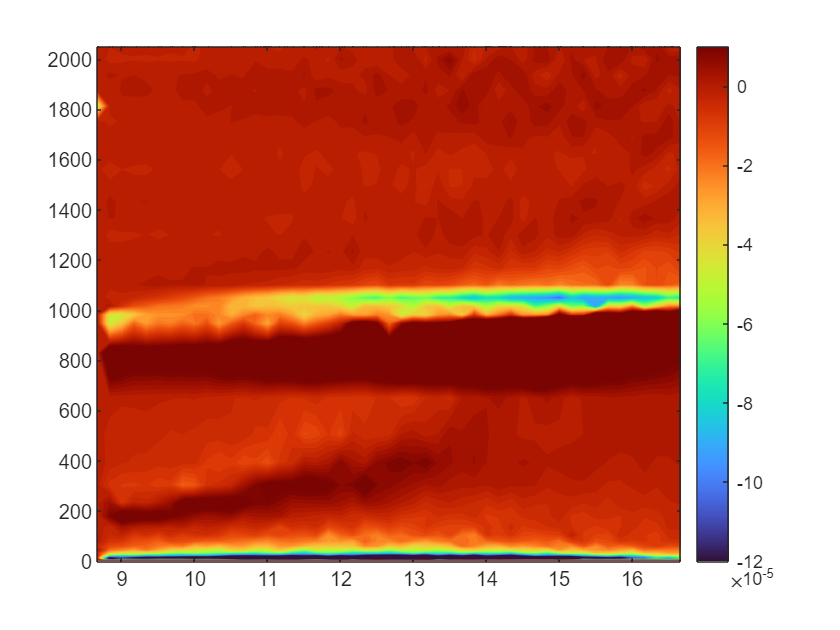

v = [0.03 0.0001 -0.1];
[C,h]=contourf(timebar(1:1:time).*10/60+8.5,ejez3,dt2,500,'EdgeColor','none');
% clabel(C,h, 'FontSize', 10, 'Color','white');
h.LineWidth = 3;
ylim([0 2050])
clim([-0.00012, 0.00001])
colormap(turbo), colorbar
c = colorbar;

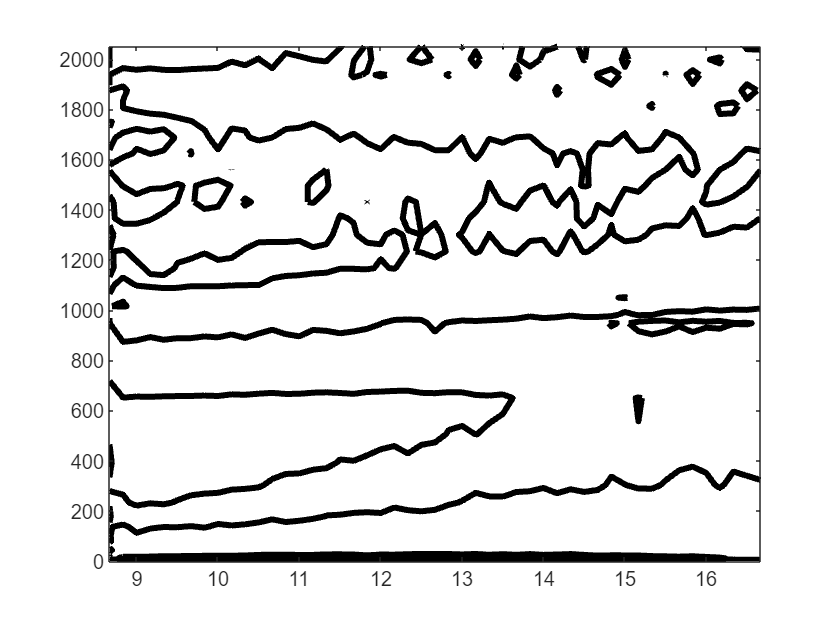

% v = [0.03 0.0001 -0.1];
[C,h]=contour(timebar(1:1:time).*10/60+8.5,ejez3,dt2,'EdgeColor','black');
% clabel(C,h, 'FontSize', 10, 'Color','white');
h.LineWidth = 3;
ylim([0 2050])